Read symbol table

Read symbol table

filename = 'C:\Users\kikim\OneDrive\Documents\GitHub\Multi_Strategy_Trading\Short_Term_Trading\IDX Stock Symbol Category Market Cap.xlsx';
sheetname = 'Final Symbols';
symdbase = readtable (filename,'Sheet', sheetname) ;

capCateg = string(unique(symdbase.CapCategory));
capCateg = sort(capCateg) ;


Load data from yahoo

% tStart = tic ;
% dataInputraw = getDataYahooIDXPVFcn_v6 (symList)
% 
% tStop = toc(tStart)


Save dataInputraw to matfile

% nsymFetched = numel(dataInputraw.volumeTT.Properties.VariableNames)
% priceVolumeDataRaw = dataInputraw
% matfilename = 'C:\Users\kikim\OneDrive\Documents\GitHub\Multi_Strategy_Trading\Short_Term_Trading\priceVolumeDataRaw.mat' ;
% save (matfilename, "priceVolumeDataRaw");


Load data from file

dataInputraw = load("priceVolumeDataRaw.mat") ;


Clean data

tStart = tic ;

dataInput = dataCleaningFcn_v3(dataInputraw);
clear dataInputraw
dataInput

tStop = toc(tStart)

Define walk window dataset

% lookback upper bound
lookbackUB = 250;

% Number of step for training datastasket
nstepTrain = 240;

% Number of step for testing dataset
nstepTest = 10;
% Number of step per walk dataset
nstepIST = lookbackUB + nstepTrain;
nstepOST = nstepTest;

% Number of walk for the whole walk forwad
nWalk = 24 ;
nstepWalk = nWalk*nstepOST + nstepIST;

% Number of rows in raw data
rowsData = size (dataInput.closepriceTT,1) ;


Walk forward  parameter optimization

startTimer = tic ; 

% preallocate paramsT
paramsvars = {'volumeMAtreshold', 'volumeMAlookback', 'valueThreshold',...
              'valueLookback', 'volumeValueBufferDays', 'priceRetLowCloseThresh',...
              'priceMAThreshold', 'priceMAlookback', 'priceVolumeValueBufferDays',...
               'cutlossLookback', 'cutlosspct'} ;
nparams = numel(paramsvars);
capvars = sort(capCateg);
ncap = numel(capvars) ; % number variables in optimParams to be optimizeds

paramsTzeros = repmat(table(zeros(nparams, 1)),[1,ncap]);
paramsT = paramsTzeros;
paramsT.Properties.VariableNames = capvars;
paramsT.Properties.RowNames = string(paramsvars) ;

% preallocate datetime
% timecol = datetime('today','Format','dd-MMM-yyyy');
% ISTenddate = repmat(datetime(timecol),1,nWalk) ;

% preallocate paramsStruct
paramsStruct = struct ;

% Table of symbol & CapCateg
symdbase.Properties.RowNames = symdbase(:,1).Variables ;
symList = eraseBetween (string(dataInput.volumeTT.Properties.VariableNames),5,11) ;
symCapCategT = symdbase(symList,[1,6]) ;


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    216   200     5     4     2     8   109    27     5     3     8


fval = -16.0219

exitflag = 0

outpt = struct with fields:
        elapsedtime: 91.5045
          funccount: 200
    constrviolation: 0
               ineq: [-0.0350 -2.9826 0 -0.1681 -0.2850]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 91.5217

optimParams_walk_i_cap_i =    216   200     5     4     2     8   109    27     5     3     8


cap_i = 3

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    116    90    16     7     8     1   166    27     3     1     4


fval = -1.4243

exitflag = 0

outpt = struct with fields:
        elapsedtime: 212.6808
          funccount: 200
    constrviolation: 0
               ineq: [-0.1307 -0.9070 0 -0.1913 -0.3307]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 212.6947

optimParams_walk_i_cap_i =    116    90    16     7     8     1   166    27     3     1     4


cap_i = 4

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     85    82     5     3     5    15    76    26     4     4     5


fval = -1.7999

exitflag = 0

outpt = struct with fields:
        elapsedtime: 82.3108
          funccount: 200
    constrviolation: 0
               ineq: [-0.0917 -1.4012 0 -0.1545 -0.3045]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 82.3442

optimParams_walk_i_cap_i =     85    82     5     3     5    15    76    26     4     4     5


cap_i = 5

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    250   170     5     7     2     1    61    30     5     2     8


fval = -7.8851

exitflag = 0

outpt = struct with fields:
        elapsedtime: 53.8830
          funccount: 200
    constrviolation: 0
               ineq: [-0.0284 -2.8951 0 -0.1233 -0.2445]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 53.8990

optimParams_walk_i_cap_i =    250   170     5     7     2     1    61    30     5     2     8


cap_i = 6

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    113   148    21     8     5    10   157    20     3     1     2


fval = -1.0958

exitflag = 0

outpt = struct with fields:
        elapsedtime: 121.6170
          funccount: 200
    constrviolation: 0
               ineq: [-0.1487 -0.1025 0 -0.1987 -0.3492]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 121.6315

optimParams_walk_i_cap_i =    113   148    21     8     5    10   157    20     3     1     2


walk_i = 3

cap_i = 1

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    245   200    17     3     2    12   118    26     3     2     7


fval = -1.8227

exitflag = 0

outpt = struct with fields:
        elapsedtime: 69.7701
          funccount: 200
    constrviolation: 0
               ineq: [-0.0370 -1.4135 0 -0.1447 -0.2817]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 69.7823

optimParams_walk_i_cap_i =    245   200    17     3     2    12   118    26     3     2     7


cap_i = 2

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    165   158     5     3    10    13    60    24     5     3     8


fval = -19.2277

exitflag = 0

outpt = struct with fields:
        elapsedtime: 74.1455
          funccount: 200
    constrviolation: 0
               ineq: [-0.0313 -3.0748 0 -0.1296 -0.2773]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 74.1600

optimParams_walk_i_cap_i =    165   158     5     3    10    13    60    24     5     3     8


cap_i = 3

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    168    99     9     8    10     7   120    24     5     3     3


fval = -2.2399

exitflag = 0

outpt = struct with fields:
        elapsedtime: 132.7706
          funccount: 200
    constrviolation: 0
               ineq: [-0.0285 -1.2979 0 -0.1582 -0.2941]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 132.7814

optimParams_walk_i_cap_i =    168    99     9     8    10     7   120    24     5     3     3


cap_i = 4

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    245   167    33     5     3     4    84    28     5     1     8


fval = -3.9241

exitflag = 0

outpt = struct with fields:
        elapsedtime: 97.7506
          funccount: 200
    constrviolation: 0
               ineq: [-0.0016 -2.0527 0 -0.1823 -0.2527]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 97.7622

optimParams_walk_i_cap_i =    245   167    33     5     3     4    84    28     5     1     8


cap_i = 5

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    248    62     5     4     9     1    94     5     3     3     4


fval = -8.6620

exitflag = 0

outpt = struct with fields:
        elapsedtime: 138.6965
          funccount: 200
    constrviolation: 0
               ineq: [-0.0028 -3.4721 0 -0.0784 -0.2810]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 138.7084

optimParams_walk_i_cap_i =    248    62     5     4     9     1    94     5     3     3     4


cap_i = 6

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    248    79    21    10    10    12   161    25     5     1     4


fval = -1.0588

exitflag = 0

outpt = struct with fields:
        elapsedtime: 112.5463
          funccount: 200
    constrviolation: 0
               ineq: [-0.1495 -0.1670 0 -0.1995 -0.3495]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 112.5590

optimParams_walk_i_cap_i =    248    79    21    10    10    12   161    25     5     1     4


walk_i = 4

cap_i = 1

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    179    55     7     3     4    13   109    30     4     2     6


fval = -2.8405

exitflag = 0

outpt = struct with fields:
        elapsedtime: 99.9579
          funccount: 200
    constrviolation: 0
               ineq: [-0.0826 -2.5616 0 -0.2000 -0.2878]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 99.9692

optimParams_walk_i_cap_i =    179    55     7     3     4    13   109    30     4     2     6


cap_i = 2

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   101   161     5     3     6    15    61    28     5     1     8


fval = -25.6553

exitflag = 0

outpt = struct with fields:
        elapsedtime: 80.5656
          funccount: 200
    constrviolation: 0
               ineq: [-0.0026 -3.2610 0 -0.2000 -0.2808]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 80.5965

optimParams_walk_i_cap_i = 1×11
   101   161     5     3     6    15    61    28     5     1     8


cap_i = 3

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   219   173     7     4     6     6   110    10     3     3     2


fval = -4.2746

exitflag = 0

outpt = struct with fields:
        elapsedtime: 105.6490
          funccount: 200
    constrviolation: 0
               ineq: [-0.0435 -2.1145 0 -0.2000 -0.3078]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 105.6616

optimParams_walk_i_cap_i = 1×11
   219   173     7     4     6     6   110    10     3     3     2


cap_i = 4

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
    80   105    12     5     2    11    85    26     4     4     8


fval = -2.1710

exitflag = 0

outpt = struct with fields:
        elapsedtime: 98.0990
          funccount: 200
    constrviolation: 0
               ineq: [-0.0474 -1.2266 0 -0.0974 -0.2474]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 98.1094

optimParams_walk_i_cap_i = 1×11
    80   105    12     5     2    11    85    26     4     4     8


cap_i = 5

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   249   199     5     7     2     1   103    13     3     1     8


fval = -10.4636

exitflag = 0

outpt = struct with fields:
        elapsedtime: 106.1303
          funccount: 200
    constrviolation: 0
               ineq: [-0.0105 -3.1437 0 -0.1281 -0.2308]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 106.1420

optimParams_walk_i_cap_i = 1×11
   249   199     5     7     2     1   103    13     3     1     8


cap_i = 6

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   206   178    19     9     8    12   147    16     5     5     2


fval = -1.1506

exitflag = 0

outpt = struct with fields:
        elapsedtime: 119.7986
          funccount: 200
    constrviolation: 0
               ineq: [-0.1428 -0.7754 0 -0.1995 -0.3433]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 119.8088

optimParams_walk_i_cap_i = 1×11
   206   178    19     9     8    12   147    16     5     5     2


walk_i = 5

cap_i = 1

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   245   151     6     5     6    11    90    30     5     1     6


fval = -4.4416

exitflag = 0

outpt = struct with fields:
        elapsedtime: 108.1519
          funccount: 200
    constrviolation: 0
               ineq: [-0.0397 -2.8349 0 -0.1712 -0.3130]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 108.1626

optimParams_walk_i_cap_i = 1×11
   245   151     6     5     6    11    90    30     5     1     6


cap_i = 2

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   238   173     5     3    10    14    98    30     4     1     8


fval = -24.0079

exitflag = 0

outpt = struct with fields:
        elapsedtime: 79.3643
          funccount: 200
    constrviolation: 0
               ineq: [-0.0458 -3.2858 0 -0.2000 -0.2601]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 79.3774

optimParams_walk_i_cap_i = 1×11
   238   173     5     3    10    14    98    30     4     1     8


cap_i = 3

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   147   161     5     5     6    15   126    26     3     1     1


fval = -3.4967

exitflag = 0

outpt = struct with fields:
        elapsedtime: 92.9605
          funccount: 200
    constrviolation: 0
               ineq: [-0.0632 -2.1763 0 -0.2000 -0.2799]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 92.9742

optimParams_walk_i_cap_i = 1×11
   147   161     5     5     6    15   126    26     3     1     1


cap_i = 4

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   241   155     5    10     2     4    63    25     5     1     8


fval = -4.3358

exitflag = 0

outpt = struct with fields:
        elapsedtime: 98.8503
          funccount: 200
    constrviolation: 0
               ineq: [-0.0132 -2.3658 0 -0.1438 -0.2470]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 98.8608

optimParams_walk_i_cap_i = 1×11
   241   155     5    10     2     4    63    25     5     1     8


cap_i = 5

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
   190   139     5     7     8     1    67     6     4     2     4


fval = -8.5630

exitflag = 0

outpt = struct with fields:
        elapsedtime: 117.8620
          funccount: 200
    constrviolation: 0
               ineq: [-0.0105 -3.5540 0 -0.1740 -0.2624]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 117.8726

optimParams_walk_i_cap_i = 1×11
   190   139     5     7     8     1    67     6     4     2     4


cap_i = 6

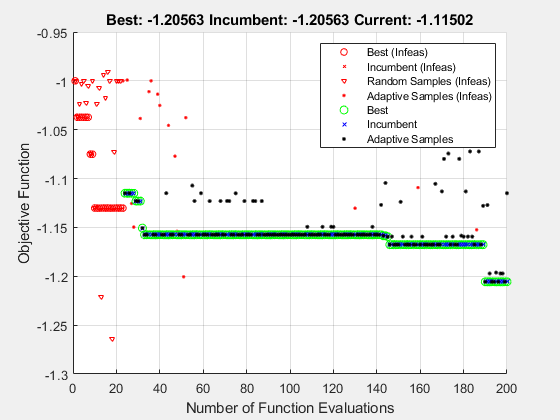

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol = 1×11
    60    56    12    10     2    15   175    27     4     1     4


fval = -1.2056

exitflag = 0

outpt = struct with fields:
        elapsedtime: 109.4295
          funccount: 200
    constrviolation: 0
               ineq: [-0.1461 -0.7799 0 -0.1987 -0.3461]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 109.4407

optimParams_walk_i_cap_i = 1×11
    60    56    12    10     2    15   175    27     4     1     4


walk_i = 6

for walk_i = 1:nWalk
    
    paramsT.Variables = paramsTzeros.Variables ; % reset paramsT
    
    % steps per walk
    OSTend_i = rowsData - nstepOST*(nWalk-walk_i) ;
    OSTstart_i = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    
    for cap_i = 1:ncap
        walk_i
        cap_i
        % symbol under cap_i
        capCateg_i = string(capCateg(cap_i)) 
        symCapCategT_i = symCapCategT(string(symCapCategT.CapCategory) == capCateg_i,:) ;
        symCapCateg_i = string(symCapCategT_i(:,1).Variables) ;
        
        % create symbol list based on end name price volume
        sym_openprice_i     = transpose(strcat(symCapCateg_i,"_open")) ;
        sym_highprice_i     = transpose(strcat(symCapCateg_i,"_high")) ;
        sym_lowprice_i      = transpose(strcat(symCapCateg_i,"_low")) ;
        sym_closeprice_i    = transpose(strcat(symCapCateg_i,"_close")) ;
        sym_volume_i    = transpose(strcat(symCapCateg_i,"_volume")) ;

        % dataset for walk_i and cap_i
        
        ISTdataSet_i.openpriceTT    = dataInput.openpriceTT(ISTstart_i:ISTend_i,sym_openprice_i) ;
        ISTdataSet_i.highpriceTT    = dataInput.highpriceTT(ISTstart_i:ISTend_i,sym_highprice_i) ;
        ISTdataSet_i.lowpriceTT     = dataInput.lowpriceTT(ISTstart_i:ISTend_i,sym_lowprice_i) ;
        ISTdataSet_i.closepriceTT   = dataInput.closepriceTT(ISTstart_i:ISTend_i,sym_closeprice_i) ;
        ISTdataSet_i.volumeTT       = dataInput.volumeTT(ISTstart_i:ISTend_i,sym_volume_i) ;
        
        % Optimize optimParams per walk
        startOptimPoint = size(ISTdataSet_i.openpriceTT,1) - nstepTrain ; % starting point of IST date
        optimParams_walk_i_cap_i = optimParamsFcn_v5 (ISTdataSet_i, startOptimPoint) 
        
        % save optimparams
        paramsT(:,cap_i).Variables = transpose(optimParams_walk_i_cap_i) ;
        
    end

    paramsStruct(walk_i).walk_i = walk_i ;
    ISTdateWalk_i = ISTdataSet_i.volumeTT.Time ;
    paramsStruct(walk_i).ISTenddate_walk_i = ISTdateWalk_i(end) ;
    paramsStruct(walk_i).paramsT = paramsT ;

end


EndTimer = toc(startTimer)  

EndTimer = 4.0551e+03

timehours = EndTimer/(60*60)

timehours = 1.1264

Save pasamStruct

save('paramsStruct.mat', "paramsStruct")

Load pasamStruct

load paramsStruct

Walk forward on optimized parameters in each walk

% Preallocate OSTportDailyRetTT 
% OSTportDailyRetTT = repmat(openpriceTT (1,1),nWalk*nstepOST,1) ;
OSTportDailyRetTT = dataInput.openpriceTT (1,1) ;
OSTportDailyRetTT.Properties.VariableNames = "OSTportDailyRet" ;

% Preallocate netDailyRetperSymTT
sym = string(dataInput.closepriceTT.Properties.VariableNames) ;
sym = eraseBetween (sym, 5,10) ;
nsym = numel(dataInput.openpriceTT.Properties.VariableNames) ;
timecol = NaT(nWalk*nstepOST,1) ;
TT = repmat(timetable(zeros(nWalk*nstepOST,1), 'RowTimes', timecol),1,nsym) ;
TT.Properties.VariableNames = sym ;
OSTnetDailyRetperSymTT = TT ;


for walk_i = 1:nWalk
    walk_i
    % steps per walk
    OSTend_i    = rowsData - nstepOST*(nWalk-walk_i) ;
    OSTstart_i  = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    for cap_i = 1:ncap
        cap_i 
        % Params walk_i & cap_i
        paramsWalki_Capi = paramsStruct(walk_i).paramsT(:,cap_i).Variables ;
        maxlookback     = max (paramsWalki_Capi([2,4,8,10],:)) ;
        
        capCateg_i = string(capCateg(cap_i)) 
        symCapCategT_i = symCapCategT(string(symCapCategT.CapCategory) == capCateg_i,:) ;
        symCapCateg_i = string(symCapCategT_i(:,1).Variables) ;
        
        % create symbol list based on end name price volume
        sym_openprice_i     = transpose(strcat(symCapCateg_i,"_open")) ;
        sym_highprice_i     = transpose(strcat(symCapCateg_i,"_high")) ;
        sym_lowprice_i      = transpose(strcat(symCapCateg_i,"_low")) ;
        sym_closeprice_i    = transpose(strcat(symCapCateg_i,"_close")) ;
        sym_volume_i    = transpose(strcat(symCapCateg_i,"_volume")) ;

        % dataset for walk_i and cap_i
        % OSTdataSet
        OSTdataSet_i.openpriceTT    = dataInput.openpriceTT(OSTstart_i-maxlookback:OSTend_i,sym_openprice_i) ;
        OSTdataSet_i.highpriceTT    = dataInput.highpriceTT(OSTstart_i-maxlookback:OSTend_i,sym_highprice_i) ;
        OSTdataSet_i.lowpriceTT     = dataInput.lowpriceTT(OSTstart_i-maxlookback:OSTend_i,sym_lowprice_i) ;
        OSTdataSet_i.closepriceTT   = dataInput.closepriceTT(OSTstart_i-maxlookback:OSTend_i,sym_closeprice_i) ;
        OSTdataSet_i.volumeTT       = dataInput.volumeTT(OSTstart_i-maxlookback:OSTend_i,sym_volume_i) ;
    
        % Walk forward params walk_i and cap_i on OST data walk_i and cap_i
        paramsInput_i = transpose(paramsWalki_Capi) ;
        tradingSignalTT_i = tradingSignalFcnVectorized_v1 (paramsInput_i, OSTdataSet_i) ;
        [~, netDailyRetperSymTT_i] = tradingBacktestFcn_v2 (tradingSignalTT_i, OSTdataSet_i);
            
        % Concatenate OSTportDailyRetTT
        OSTnetDailyRetperSymTT_i = netDailyRetperSymTT_i(end-nstepOST+1:end,:) ; 
        
        startIdx    = 1 + nstepOST*(walk_i - 1)
        endIdx      = startIdx + nstepOST - 1

        OSTnetDailyRetperSymTT (startIdx:endIdx,transpose(symCapCateg_i)) = OSTnetDailyRetperSymTT_i  ; 
        OSTnetDailyRetperSymTT.Time(startIdx:endIdx,:) = OSTnetDailyRetperSymTT_i.Time ;
        
    end
end

walk_i = 1

cap_i = 1

capCateg_i = "LowerBigCap"

startIdx = 1

endIdx = 20

cap_i = 2

capCateg_i = "LowerMidCap"

startIdx = 1

endIdx = 20

cap_i = 3

capCateg_i = "LowerSmallCap"

startIdx = 1

endIdx = 20

cap_i = 4

capCateg_i = "UpperBigCap"

startIdx = 1

endIdx = 20

cap_i = 5

capCateg_i = "UpperMidCap"

startIdx = 1

endIdx = 20

cap_i = 6

capCateg_i = "UpperSmallCap"

startIdx = 1

endIdx = 20

walk_i = 2

cap_i = 1

capCateg_i = "LowerBigCap"

startIdx = 21

endIdx = 40

cap_i = 2

capCateg_i = "LowerMidCap"

startIdx = 21

endIdx = 40

cap_i = 3

capCateg_i = "LowerSmallCap"

startIdx = 21

endIdx = 40

cap_i = 4

capCateg_i = "UpperBigCap"

startIdx = 21

endIdx = 40

cap_i = 5

capCateg_i = "UpperMidCap"

startIdx = 21

endIdx = 40

cap_i = 6

capCateg_i = "UpperSmallCap"

startIdx = 21

endIdx = 40

walk_i = 3

cap_i = 1

capCateg_i = "LowerBigCap"

startIdx = 41

endIdx = 60

cap_i = 2

capCateg_i = "LowerMidCap"

startIdx = 41

endIdx = 60

cap_i = 3

capCateg_i = "LowerSmallCap"

startIdx = 41

endIdx = 60

cap_i = 4

capCateg_i = "UpperBigCap"

startIdx = 41

endIdx = 60

cap_i = 5

capCateg_i = "UpperMidCap"

startIdx = 41

endIdx = 60

cap_i = 6

capCateg_i = "UpperSmallCap"

startIdx = 41

endIdx = 60

walk_i = 4

cap_i = 1

capCateg_i = "LowerBigCap"

startIdx = 61

endIdx = 80

cap_i = 2

capCateg_i = "LowerMidCap"

startIdx = 61

endIdx = 80

cap_i = 3

capCateg_i = "LowerSmallCap"

startIdx = 61

endIdx = 80

cap_i = 4

capCateg_i = "UpperBigCap"

startIdx = 61

endIdx = 80

cap_i = 5

capCateg_i = "UpperMidCap"

startIdx = 61

endIdx = 80

cap_i = 6

capCateg_i = "UpperSmallCap"

startIdx = 61

endIdx = 80

walk_i = 5

cap_i = 1

capCateg_i = "LowerBigCap"

startIdx = 81

endIdx = 100

cap_i = 2

capCateg_i = "LowerMidCap"

startIdx = 81

endIdx = 100

cap_i = 3

capCateg_i = "LowerSmallCap"

startIdx = 81

endIdx = 100

cap_i = 4

capCateg_i = "UpperBigCap"

startIdx = 81

endIdx = 100

cap_i = 5

capCateg_i = "UpperMidCap"

startIdx = 81

endIdx = 100

cap_i = 6

capCateg_i = "UpperSmallCap"

startIdx = 81

endIdx = 100

walk_i = 6

cap_i = 1

capCateg_i = "LowerBigCap"

startIdx = 101

endIdx = 120

cap_i = 2

capCateg_i = "LowerMidCap"

startIdx = 101

endIdx = 120

cap_i = 3

capCateg_i = "LowerSmallCap"

startIdx = 101

endIdx = 120

cap_i = 4

capCateg_i = "UpperBigCap"

startIdx = 101

endIdx = 120

cap_i = 5

capCateg_i = "UpperMidCap"

startIdx = 101

endIdx = 120

cap_i = 6

capCateg_i = "UpperSmallCap"

startIdx = 101

endIdx = 120

Analyze the results

plot chart animation

walkStart_i = 1

walkEnd_i = 20

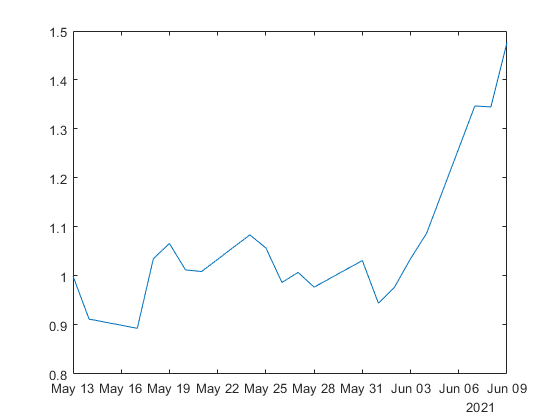

walkStart_i = 21

walkEnd_i = 40

walkStart_i = 41

walkEnd_i = 60

walkStart_i = 61

walkEnd_i = 80

walkStart_i = 81

walkEnd_i = 100

walkStart_i = 101

walkEnd_i = 120

% Plot animated chart with pause or drawnow function
% Plot portCumRetTT    
% Plot animated chart with pause or drawnow function

OSTportDailyRet     = sum(OSTnetDailyRetperSymTT.Variables,2) ;
OSTportDailyRetTT   = timetable(OSTportDailyRet, 'RowTimes', OSTnetDailyRetperSymTT.Time, 'VariableNames', "OSTportDailyRet") ;
OSTportCumRetTT     = ret2tick (OSTportDailyRetTT) ;

for walk_i = 1:nWalk
%     i = 2
%     walk_i = walk_i 

    walkStart_i = 1+ nstepOST*(walk_i-1)
    walkEnd_i = walkStart_i + nstepOST-1
    OSTportCumRetTT_i = OSTportCumRetTT(1:walkEnd_i, :);
    
%     semilogy(OSTportCumRetTT_i.Time, OSTportCumRetTT_i.Variables)
    plot(OSTportCumRetTT_i.Time, OSTportCumRetTT_i.Variables)
    drawnow 
    pause(2);

end

Plot the equity curve on OST dataset

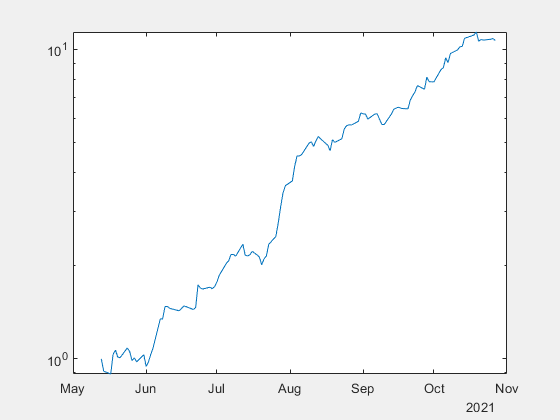

OSTportDailyRet     = sum(OSTnetDailyRetperSymTT.Variables,2) ;
OSTportDailyRetTT   = timetable(OSTportDailyRet, 'RowTimes', OSTnetDailyRetperSymTT.Time, 'VariableNames', "OSTportDailyRet") ;
OSTportCumRetTT     = ret2tick (OSTportDailyRetTT) ;
semilogy(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)

Statistics

% OSTportCumRetTT = ret2tick (OSTportDailyRetTT) ;
% 
% plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)

% CAGR
timeVar = OSTportCumRetTT.Time ;
OSTportCumRet = OSTportCumRetTT.Variables ;
OSTportCumRetEnd = OSTportCumRet(end,:)

OSTportCumRetEnd = 10.6946

nYear = yearfrac (timeVar(1,:), timeVar(end,:))

nYear = 0.4575

CAGR = ((OSTportCumRet (end,:) / OSTportCumRet (1,:))^(1/nYear)) - 1

CAGR = 176.5692

MonthlyRet = (1+CAGR)^(1/12) - 1

MonthlyRet = 0.5397


% Drawdown
[MDD,MaxDDIndex] = maxdrawdown(OSTportCumRetTT.Variables) ;
MaxDD = MDD 

MaxDD = 0.1424

drawDownTime = timeVar(MaxDDIndex)

drawDownTime = 2×1 datetime array
   12-Jul-2021
   20-Jul-2021


Number signal daily

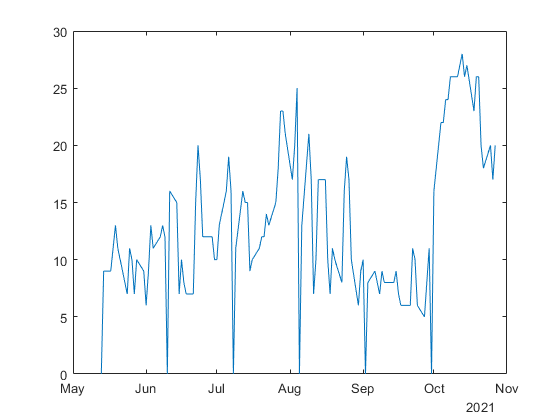

tradingSignal = (OSTnetDailyRetperSymTT.Variables > 0) + (OSTnetDailyRetperSymTT.Variables < 0) ;
nDailySignal = sum (tradingSignal,2) ;
nDailySignalTT = OSTportCumRetTT ;
nDailySignalTT.Variables = nDailySignal ;
nDailySignalTT.Properties.VariableNames = "nDailySignal" ;

% plot daily signal
plot(nDailySignalTT.Time , nDailySignalTT.Variables )

Rank symbol based on cumulative return

symRank = rankSymbolsFcn (OSTnetDailyRetperSymTT);

symRank = 745×2 table
     symbol     Cumulative Return
    ________    _________________

    {'BOLA'}       {[1.2774]}    
    {'BEBS'}       {[1.2302]}    
    {'BABP'}       {[1.1877]}    
    {'MLPL'}       {[1.1796]}    
    {'BHIT'}       {[1.1348]}    
    {'RANC'}       {[1.1216]}    
    {'NFCX'}       {[1.1179]}    
    {'TECH'}       {[1.1152]}    
    {'MSIN'}       {[1.1073]}    
    {'SAMF'}       {[1.1069]}    
    {'REAL'}       {[1.1018]}    
    {'RUNS'}       {[1.0885]}    
    {'BCAP'}       {[1.0805]}    
    {'FREN'}       {[1.0777]}    
    {'SBMA'}       {[1.0755]}    
    {'MMLP'}       {[1.0754]}    


Discretionary

OSTCumRetperSymTT = ret2tick(OSTnetDailyRetperSymTT) ;

plot(OSTCumRetperSymTT.Time, OSTCumRetperSymTT.BABP)

Save optimParams to matfile

% Save optimParams to matfile
optimParams_filename = "optimParams.mat";
save (optimParams_filename , "optimParamsTable") 


Stock pick

tradingSignalTT = OSTnetDailyRetperSymTT ;
tradingSignalTT.Variables = tradingSignal ;

stockPickOut = stockpickFcn_v1 (tradingSignalTT) 

stockPickOut = 20×2 table
     Symbol     TradingSignal
    ________    _____________

    {'ADRO'}        {[1]}    
    {'BBNI'}        {[1]}    
    {'BRIS'}        {[1]}    
    {'BUMI'}        {[1]}    
    {'DSNG'}        {[1]}    
    {'EMTK'}        {[1]}    
    {'ISAT'}        {[1]}    
    {'KLBF'}        {[1]}    
    {'LSIP'}        {[1]}    
    {'MIDI'}        {[1]}    
    {'MLPL'}        {[1]}    
    {'PNLF'}        {[1]}    
    {'PTBA'}        {[1]}    
    {'SAME'}        {[1]}    
    {'SCMA'}        {[1]}    
    {'SIMP'}        {[1]}    
